#### EX 2-1 变量创建与赋值

% 定义变量a为1并输出
a = 1

a = 1

% 定义变量b为2但不输出
b = 2;
% 变量c为a+b的计算结果并输出
c = a+b

c = 3

% 计算a*b，但不赋值直接输出
a*b

ans = 2

#### EX 2-2 矩阵操作基础

% 赋值a为行向量（1x3矩阵）
a = [1 2 3]

a =      1     2     3


% 赋值b为2x3矩阵
b = [1 2 3; 4 5 6]

b =      1     2     3
     4     5     6


% 赋值c为2x3的零矩阵
c = zeros(2,3)

c =      0     0     0
     0     0     0


% d为a的转置
d = a'

d =      1
     2
     3


% e为a与c的矩阵的垂直
e = [a; c]

e =      1     2     3
     0     0     0
     0     0     0


% f为b与c的矩阵的水平串联
f = [b,c]

f =      1     2     3     0     0     0
     4     5     6     0     0     0


#### EX 2-3 矩阵计算基础

% a: [1 2; 3 4]
a = [1 2; 3 4]

a =      1     2
     3     4


% b: a的所有元素加2
b = a+2

b =      3     4
     5     6


% c: a的所有元素都取正弦
c = sin(a)

c =     0.8415    0.9093
    0.1411   -0.7568


% d: a矩阵取逆
d = inv(a)

d =    -2.0000    1.0000
    1.5000   -0.5000


% e: 矩阵乘法
e = a*d

e =     1.0000         0
    0.0000    1.0000


% f: 对应元素相乘
f = a.*d

f =    -2.0000    2.0000
    4.5000   -2.0000


#### EX 2-4 `矩阵索引基础`

% a:[1 2; 3 4; 5 6]
a = [1 2; 3 4; 5 6]

a =      1     2
     3     4
     5     6


% b:提取a中第3行第2列的元素
b = a(3,2)

b = 6

% c:提取a中的第2个元素
c = a(2)

c = 3

% d:将a化为向量形式
d = a(:)

d =      1
     3
     5
     2
     4
     6


% e:a中第1行所有元素组成的阵
e = a(1,:)

e =      1     2


% 将a中的第2行删去
a(2,:) = []

a =      1     2
     5     6


#### EX 2-5 字符型矩阵

% a:字符串"Hello, World!"
a = 'Hello, World!'

a = 'Hello, World!'

% b:提取a的第1个字符
b = a(1)

b = 'H'

% c:显示矩阵a的类型
c = class(a)

c = 'char'

% d:按串联字符矩阵
d = [a ' I am coming']

d = 'Hello, World! I am coming'

% e:在字符串中输入特殊字符
e = [a ' I''m coming']

e = 'Hello, World! I'm coming'

#### EX 2-6 图形可视化原理

% x:向量0~2pi，间隔为0.1
x = 0:0.1:2*pi

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


% y:取x每个元素的正弦
y = sin(x)

y =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


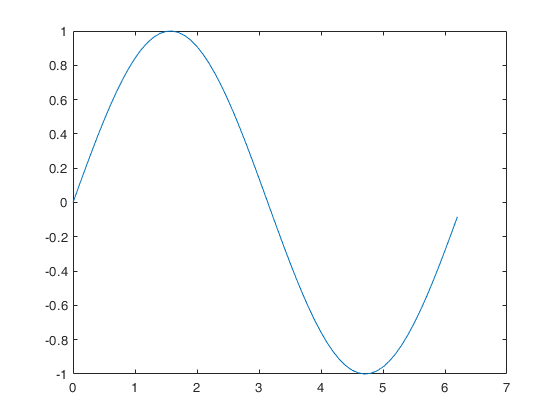

% 绘图x-y
plot(x,y)

将向量的间隔放大一些，会发生什么？

% x:向量0~2pi，间隔为1
x = 0:1:2*pi

x =      0     1     2     3     4     5     6


% y:取x每个元素的正弦
y = sin(x)

y =          0    0.8415    0.9093    0.1411   -0.7568   -0.9589   -0.2794


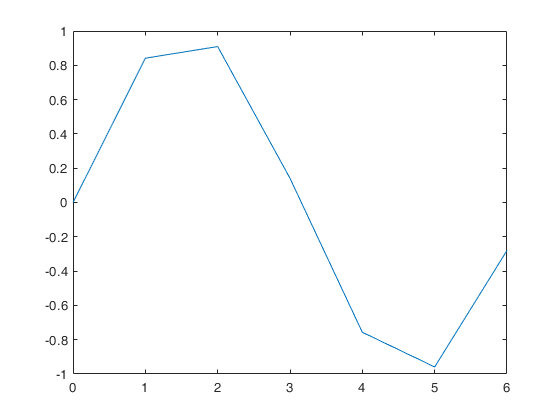

% 再次绘图x-y
plot(x,y)

#### EX 2-7 `包含多组数据的绘图`

% x:向量0~2pi，间隔为0.1
x = 0:0.1:2*pi;
% y1/y2/y3:不同相位的正弦
y1 = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);
% 绘图x-y
plot(x,y1,x,y2,x,y3)

为图形加上图例、标签、标题：

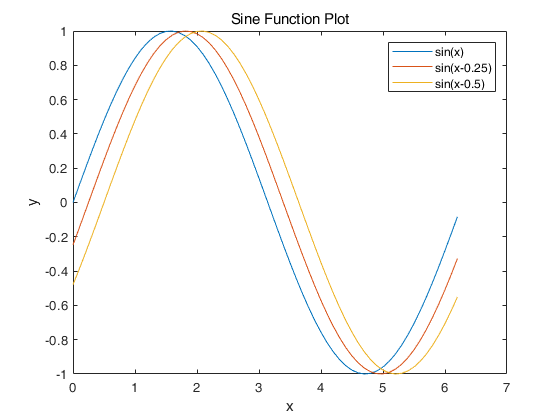

% 图例
legend('sin(x)',...
    'sin(x-0.25)',...
    'sin(x-0.5)')
% 轴标签
xlabel('x')
ylabel('y')
% 标题
title('Sine Function Plot')

#### EX 2-8 三维绘图

% 生成网格矩阵
[X,Y] = meshgrid(-2:0.1:2); 
% 探查X的尺寸
sizeX = size(X)

sizeX =     41    41


三维函数——


$$z=xe^{-x^2 -y^2 }$$


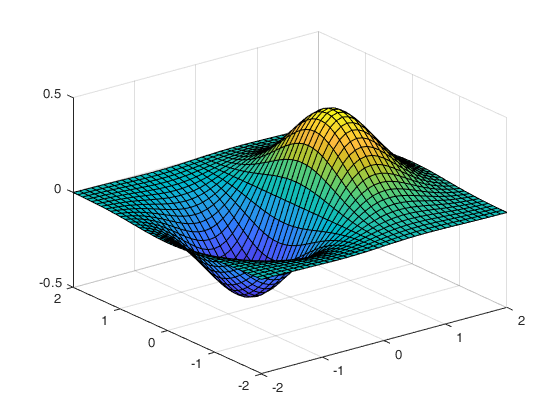

% Z: 按函数创建
Z = X .* exp(-X.^2 - Y.^2);
% 创建曲面图
surf(X,Y,Z)

#### EX 2-9 子图绘制-subplot

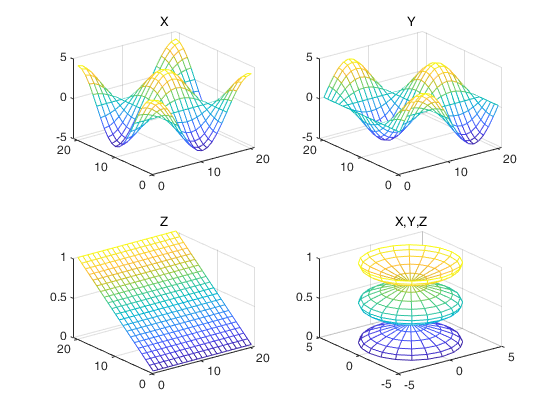

% 参数t
t = 0:pi/10:2*pi;
% 返回半径为4*cos(t)的圆柱网格
[X,Y,Z] = cylinder(4*cos(t));
% 矩阵图尺寸为2x2
subplot(2,2,1); 
mesh(X); title('X');
subplot(2,2,2); 
mesh(Y); title('Y');
subplot(2,2,3); 
mesh(Z); title('Z');
subplot(2,2,4); 
mesh(X,Y,Z); title('X,Y,Z');

#### EX 2-10 线性代数

1. 求矩阵的逆、行列式、秩、迹

B = [2 3; 0 1];
% 矩阵的逆
inv(B)

ans =     0.5000   -1.5000
         0    1.0000


% 矩阵的行列式
det(B)

ans = 2

% 矩阵的秩
rank(B)

ans = 2

% 矩阵的迹
trace(B)

ans = 3

2. 求矩阵的特征值矩阵与特征向量阵

% V:特征向量矩阵
% D:特征值矩阵
[V, D] = eig(B)

V =     1.0000   -0.9487
         0    0.3162


D =      2     0
     0     1


3. 解线性方程 Ax=b：


$$\left\lbrace \begin{array}{cc}
x+2y=5 & \left(1\right)\\
2x-y=0 & \left(2\right)
\end{array}\right.$$


% 定义A和b
A = [1 2; 2 -1]

A =      1     2
     2    -1


b = [5 0]';
% 解方程
x = A\b

x =      1
     2


#### EX 2-11 微积分

1. 求导数

% 定义一个符号对象x
syms x
% 定义一个符号函数f
f = x^2+x

$$f = x^{2}+x$$

% 求f的导数-解析解
f1 = diff(f)

$$f1 = 2\,x+1$$

2. 求不定积分

f2 = int(f, x)

$$f2 = \frac{x^{2}\,\left(2\,x+3\right)}{6}$$

3. 求定积分

% 求区间[0,2]上的定积分
f3 = int(f, x, 0, 2)

$$f3 = \frac{14}{3}$$

4. 求泰勒展开

% 在x=1位置泰勒展开
f4 = taylor(f, x, 1)

$$f4 = 3\,x+{\left(x-1\right)}^{2}-1$$

% 令x为1，进行验证
x = 1;
subs(f)

$$ans = 2$$

subs(f4)

$$ans = 2$$

#### EX 2-12 微分方程

1. 微分方程解析解


$$\frac{\textrm{dy}}{\textrm{dt}}\;=\;\textrm{ay}$$


% 定义符号常量a和符号函数y(t) 
syms a y(t)
% eqn:定义符号方程式
eqn = diff(y,t) == a*y

$$eqn(t) = \frac{\partial }{\partial t}y\left(t\right)=a\,y\left(t\right)$$

% 解方程
ySol(t) = dsolve(eqn)

$$ySol(t) = C_{1}\,{\mathrm{e}}^{a\,t}$$

2. 高阶微分方程解析解


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y=\textrm{ay}$$


syms a y(t)
eqn = diff(y,t,2) == a*y

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=a\,y\left(t\right)$$

ySol(t) = dsolve(eqn)

$$ySol(t) = C_{1}\,{\mathrm{e}}^{-\sqrt{a}\,t}+C_{2}\,{\mathrm{e}}^{\sqrt{a}\,t}$$

3. 带有初始条件的微分方程解析解


$$\frac{\textrm{dy}}{\textrm{dt}}\;=\;\textrm{ay}$$
 
$$y\left(0\right)=5$$


syms a y(t)
eqn = diff(y,t) == a*y

$$eqn(t) = \frac{\partial }{\partial t}y\left(t\right)=a\,y\left(t\right)$$

cond = y(0) == 5

$$cond = y\left(0\right)=5$$

ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 5\,{\mathrm{e}}^{a\,t}$$

#### EX 2-13 概率统计

1. 数据预处理

% 清空内存数据和图表
clear; clf;
% 加载count.dat中的数据
load count.dat; data = count(:,3);

2. 数据汇总

% 平均值
mu = mean(data)

mu = 65.5833

% 标准差
sigma = std(data)

sigma = 68.0281

3. `可视化`

% 绘制直方分布图
h = histogram(data, 12)

h =   Histogram - 属性:

             Data: [24×1 double]
           Values: [10 2 2 3 2 1 1 0 2 0 0 1]
          NumBins: 12
         BinEdges: [0 22 44 66 88 110 132 154 176 198 220 242 264]
         BinWidth: 22
        BinLimits: [0 264]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


hold on
% 平均值线
plot([mu mu],[0 10])

4. 建模

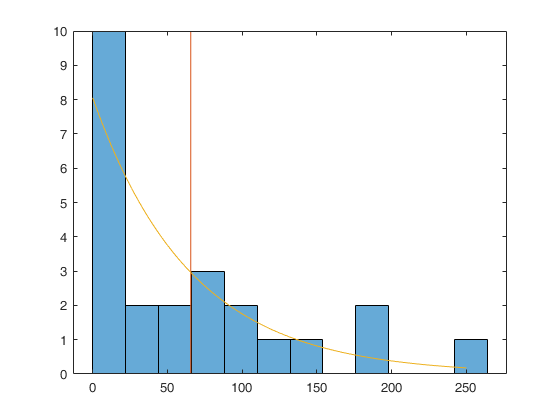

% 计算直方面积
area = h.BinWidth*size(data,1);
% 指数分布密度函数
t = 0:250;
exp_pdf = @(t)(1/mu)*exp(-t/mu); 
plot(t,area*exp_pdf(t))

#### EX 2-14 if控制流

1. if - end

a = 1;
if a == 1 % 如果a等于1
    disp('Yes! a==1');
end

Yes! a==1


2. if - else - end

a = 1;
if a == 1 % 如果a等于1
    disp('Yes! a==1');
else % 否则的话
    disp('No. a~=1');
end

Yes! a==1


3. if - elseif - else - end

a = 2;
if a == 1 % 如果a等于1
    disp('Yes! a==1');
elseif a == 2 % 否则，如果a等于2
    disp('Yes! a==2');
else % 再否则
    % 什么都不做    
end

Yes! a==2


#### EX 2-15 for控制流

1. for - end 向量中元素循环

for i = 1:4
    i
end

i = 1

i = 2

i = 3

i = 4

2. for - end 矩阵中向量循环

a = [1 2; 3 4];
for i = a
    i
end

i =      1
     3


i =      2
     4


3. for - end 矩阵中元素循环

a = [1 2; 3 4];
for i = a(:)'
    i
end

i = 1

i = 3

i = 2

i = 4

#### EX 2-16 矩阵编程

1. 矩阵函数

a = [1 3 2 4];
% 求a中所有元素的平均值
b = mean(a)

b = 2.5000

% 对a进行从小到大排序
c = sort(a)

c =      1     2     3     4


% 求a中持有元素的和
d = sum(a)

d = 10

2. 逻辑角标

a = [1 3 2 4];
% 找到a中比2大的元素的索引
b = find(a>2)

b =      2     4


% 生成a中2大的元素的逻辑矩阵
c = a > 2

c = 1×4 logical 数组
   0   1   0   1


% 将被逻辑矩阵c指定的元素变成0
a(c) = 0

a =      1     0     2     0
